# eqlim example of element

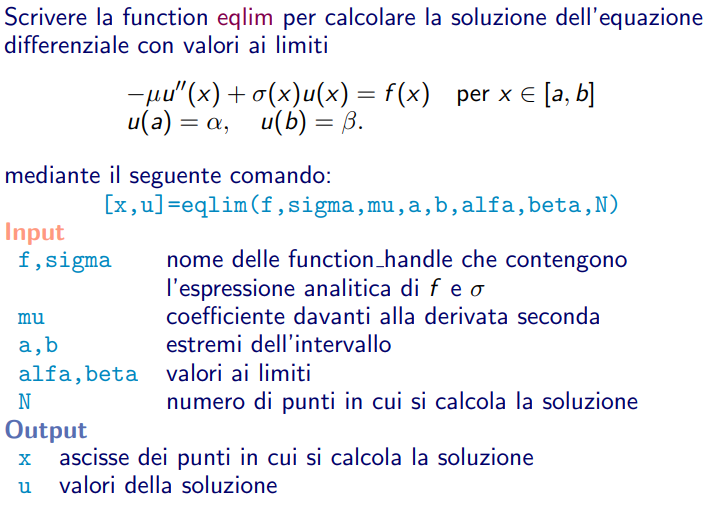

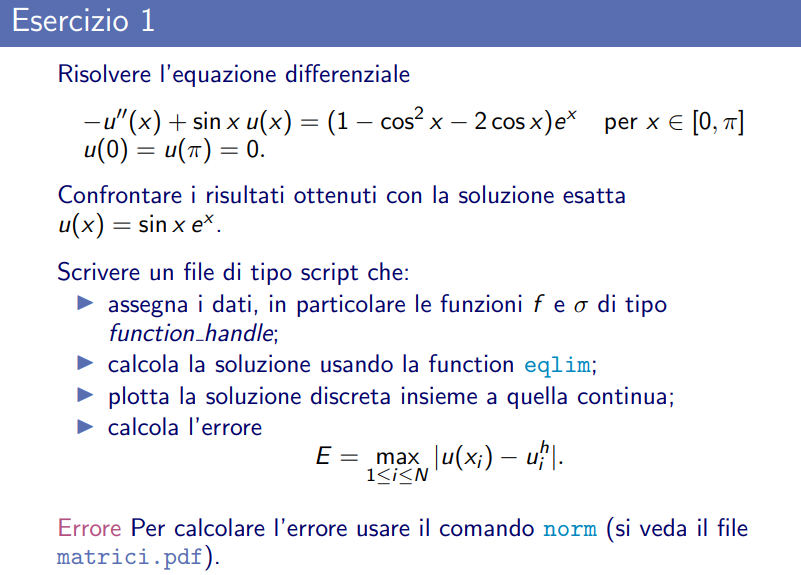

clear all
close all

f = @(x) (1-cos(x).^2 - 2*cos(x)).*exp(x);
sigma = @(x) sin(x);
mu =1; %termine davanti a u'' escluso il meno
alpha = 0;
beta = 0;
a = 0;
b = pi;
N = 100;
[x,u,h] = eqlim(f,sigma,mu,a,b,alpha,beta,N);
figure
plot(x,u)
hold on
y = @(x) sin(x).*exp(x)

y = function_handle with value:
    @(x)sin(x).*exp(x)

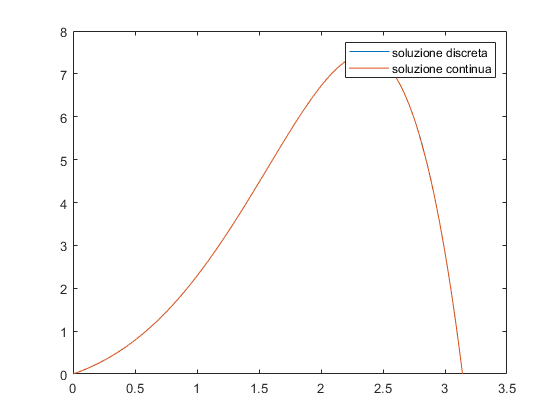

fplot(y,[0 pi])
legend("soluzione discreta","soluzione continua")

errore = norm(u-y(x),inf)

errore = 0.0010

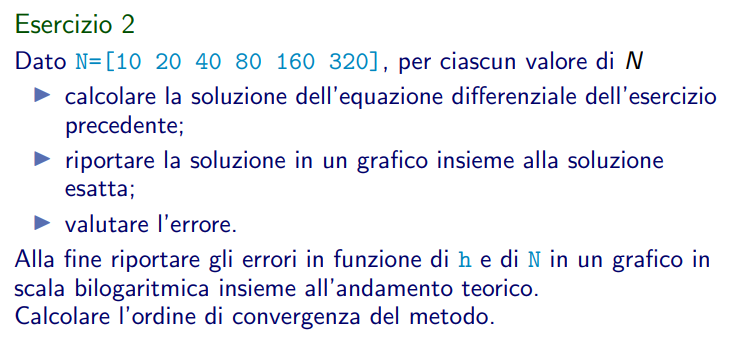

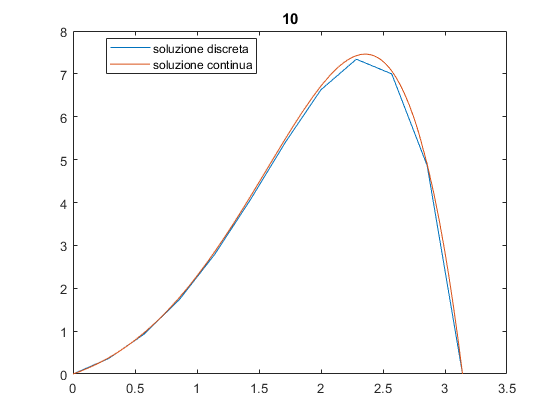

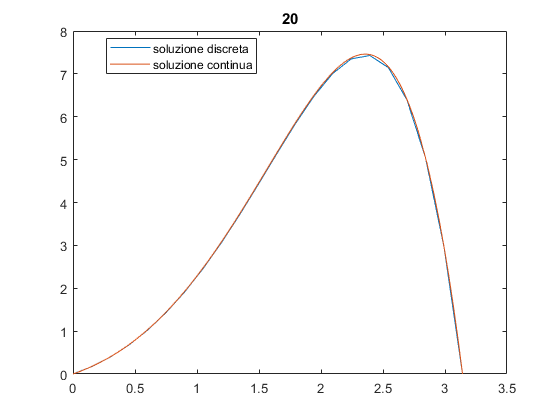

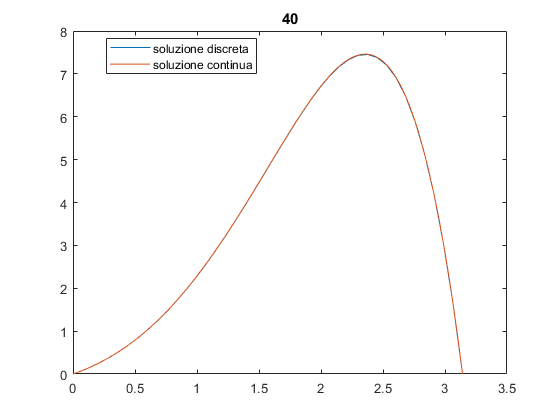

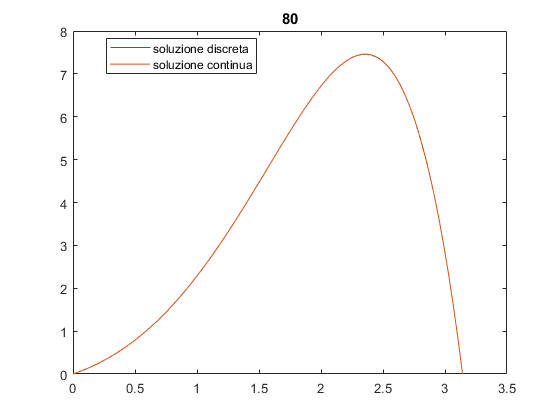

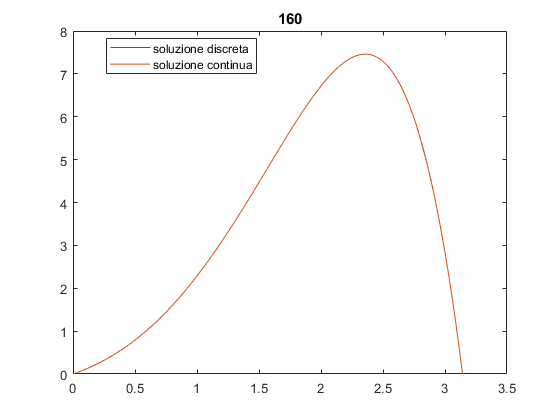

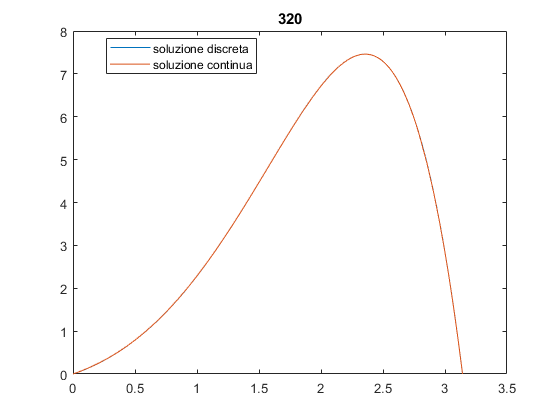

N = [10 20 40 80 160 320];
y = @(x) sin(x).*exp(x);
errore = zeros(1,length(N));
h=zeros(1,length(N));
for i = 1:1:length(N)
    [x,u,h(i)] = eqlim(f,sigma,mu,a,b,alpha,beta,N(i));
    figure
    plot(x,u)
    title(N(i))
    hold on
    fplot(y,[0 pi])
    legend("soluzione discreta","soluzione continua","location","best")
    errore(i) = norm(u-y(x),inf);
end

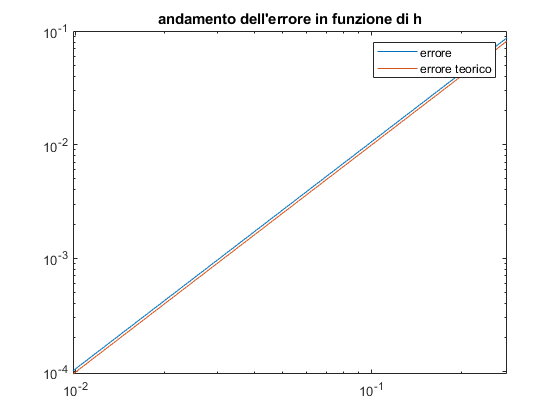

figure
loglog(h,errore)
hold on
loglog(h,h.^2)
legend("errore","errore teorico")
title("andamento dell'errore in funzione di h")

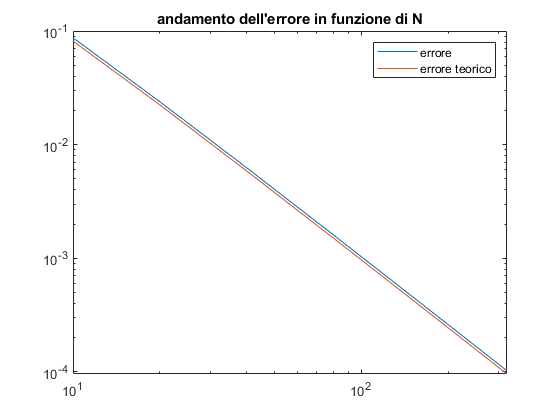

figure
loglog(N,errore)
hold on
loglog(N,h.^2)
legend("errore","errore teorico")
title("andamento dell'errore in funzione di N")

%ordine di convergenza è 2 perche segue h alla seconda.